# Transformación Invariante de Upcroft

## ¿Qué es?

La transformación invariante de Upcroft es un método que genera imágenes robustas a variaciones en la iluminación, incluyendo sombras y cambios de intensidad. El método se basa en la relación logarítmica entre los canales de color y se utiliza para mejorar la clasificación de escenas urbanas en entornos cambiantes.

## Funcionamiento básico de la transformación

**1. Modelo espectral RGB:**

Aunque no aparece explicitamente en el artículo, se menciona que el método de transformación invariante se basa en la relación logarítmica entre los canales RGB y hace referencia a trabajos anteriores como los de Ratnasingam y Collins. La respuesta espectral de un canal específico $\rho_k$ (con 𝑘={𝑟,𝑔,𝑏}) se define como:


$$\rho_k = \sigma \int E(\lambda) S(\lambda) Q_k(\lambda) d\lambda$$


donde:

- $\sigma$: factor constante que denota el sombreado de Lambert.

- $E(\lambda)$: iluminación incidente en el elemento de superficie percibida.

- $S(\lambda)$: reflectancia espectral de la superficie.

- $Q(\lambda)$: sensibilidad espectral del canal $k$.

- $\lambda$: longitud de onda.

**2. Transformación logarítmica:**

La transformación invariante utiliza la relación logarítmica entre los canales $RGB$ para minimizar la variabilidad causada por la geometría, la intensidad y el espectro de la fuente de luz.


$$F = \log(G) - \alpha \log(B) - (1 - \alpha) \log(R)$$


**3. Cálculo del parámetro **$\alpha$**:**

El parámetro $\alpha$ se calcula para minimizar la variabilidad de la fuente de luz. Esto se logra utilizando las longitudes de onda pico de los sensores:


$$\frac{1}{\lambda_G} = \frac{\alpha}{\lambda_B} + \frac{1 - \alpha}{\lambda_R}$$


## Análisis de la implementación:

**1. Parámetros de entrada:**

- $RGB$: imagen en formato RGB.

- $alpha$: parámetro para aproximación logarítmica.

**2. Separación de los canales:**

Primero, la función guarda por separado cada canal de la imagen, $R$, $G$ y $B$.

R = double(RGB(:,:,1));
G = double(RGB(:,:,2));
B = double(RGB(:,:,3));

**3. Calculo del parámetro **$\alpha$

El parámetro $\alpha

$ se cancula en una función a parte y se pasa como parámetro.

alpha = (lambda3 / (lambda3 - lambda1)) * (1/lambda2 - 1/lambda3);

**4. Transformación invariante:**

Finalmente, la función realiza la transformación invariante con parámetro $\alpha$:

I_Upcroft = log(G) - alpha*log(B) - (1 - alpha)*log(R);

### Código completo

function alpha = calcular_alpha(lambda1, lambda2, lambda3)
    alpha = (lambda3 / (lambda3 - lambda1)) * (1/lambda2 - 1/lambda3);
end

function I_Upcroft = upcroft_transform(RGB, alpha)
    % Separación de la imagen RGB por canales en double
    R = double(RGB(:,:,1));
    G = double(RGB(:,:,2));
    B = double(RGB(:,:,3));
    
    % Transformación invariante
    I_Upcroft = log(G) - alpha*log(B) - (1 - alpha)*log(R);
end

Un ejemplo de una imagen del programa y su correspondiente transformación:

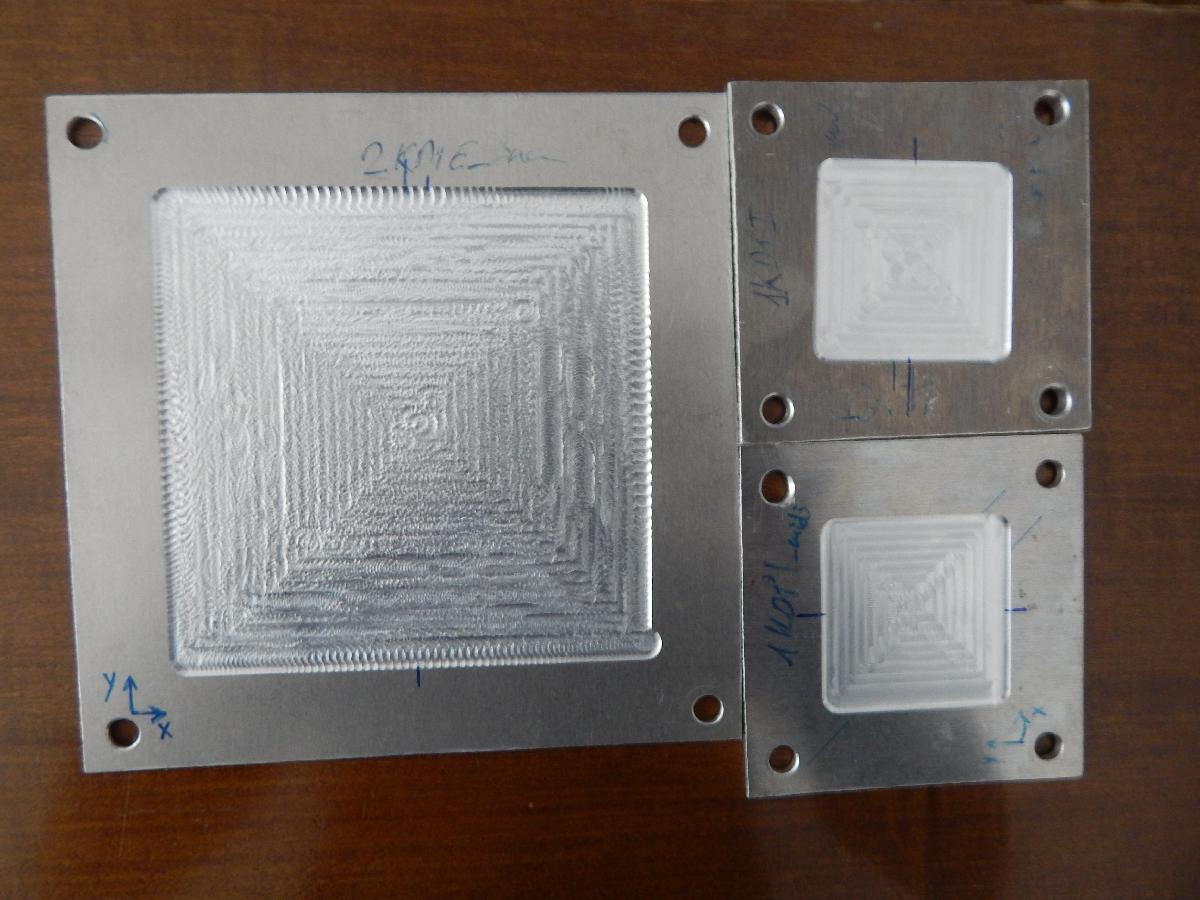    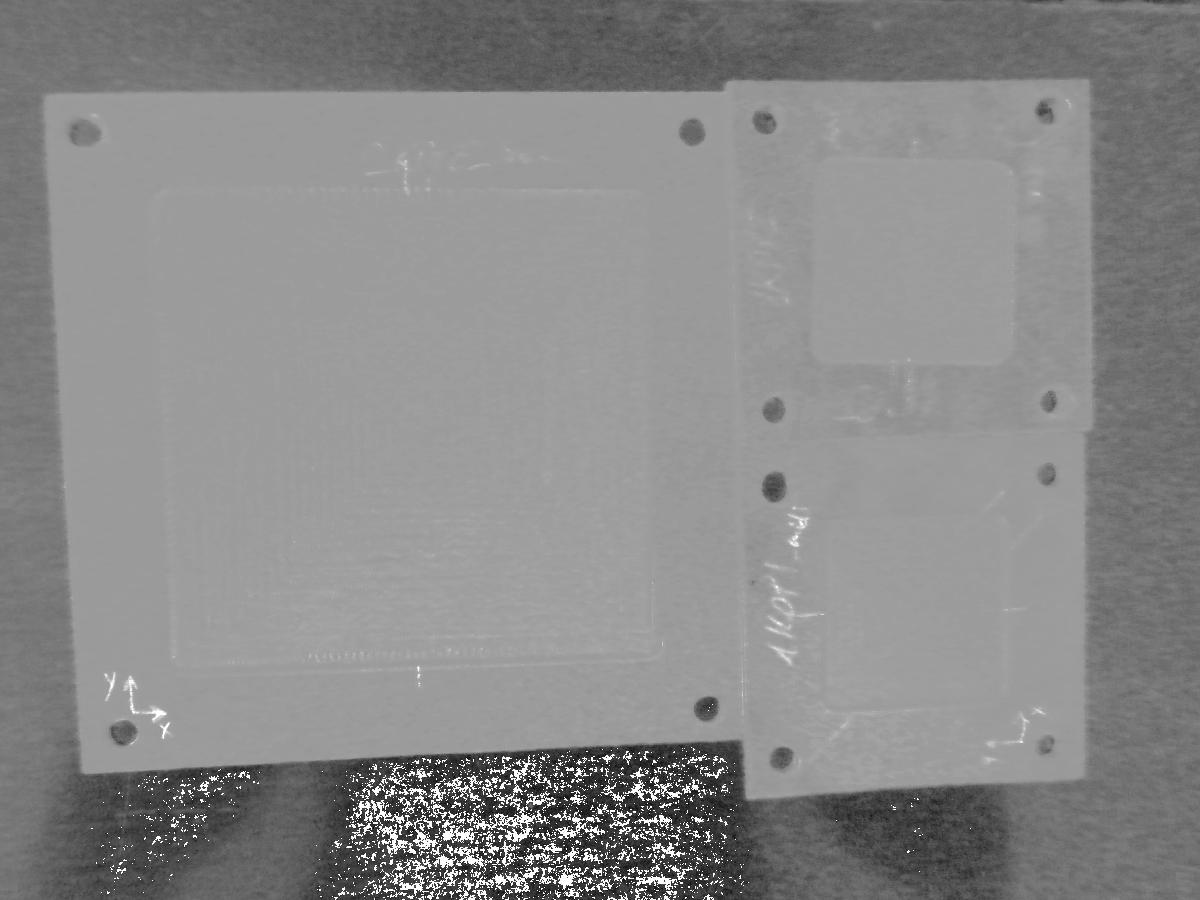

## Referencias

- Upcroft, B., McManus, C., Churchill, W., Maddern, W., & Newman, P. "Lighting invariant urban street classification," *IEEE International Conference on Robotics and Automation (ICRA)*, pp. 1712-1718, 2014.

- Ratnasingam, S., & Collins, S. (2010). Study of the photodetector characteristics of a camera for color constancy in natural scenes. *Journal of the Optical Society of America A*, 27(2), 233-240.

- Ratnasingam, S., & McGinnity, T. M. (2012). Chromaticity space for illuminant invariant recognition. *IEEE Transactions on Image Processing*, 21(8), 3612-3623.